clear;
clc;

% Lapso temporal
t = linspace(0, 3e4, 1e6);

% Constantes (SSO)
mu = 3.986004418e14;
J2 = 1.082635854e-3;
R = 6378.137e3;
a = 7211.54e3;
e = 0.01;
n = sqrt(mu ./ a.^3);
INC     = deg2rad(98.7);
Omega   = deg2rad(0);
omega   = deg2rad(30);
theta_0 = deg2rad(0);

% Condiciones iniciales
x0I  =  6182.923072003555e3;
y0I  = - 539.9576105445875e3;
z0I  =  3528.638786215765e3;
dx0I = - 3.754637152801252e3;
dy0I = - 0.9836827412595693e3;
dz0I =   6.428395500600019e3;
x0   = 0;
y0   = 0;
z0   = 0;
dx0  = 0;
dy0  = 0;
dz0  = 0;

% Solución analítica
xB = (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*(- (y0.*(32.*a.*n - 128.*a.*e.^2.*n + 192.*a.*e.^4.*n - 128.*a.*e.^6.*n + 32.*a.*e.^8.*n))./(32.*a.*n.*(e.^2 - 1).^4) + (dx0.*(128.*a.*sin((n.*t)./2).^2 - 512.*a.*e.^2.*sin((n.*t)./2).^2 + 768.*a.*e.^4.*sin((n.*t)./2).^2 - 512.*a.*e.^6.*sin((n.*t)./2).^2 + 128.*a.*e.^8.*sin((n.*t)./2).^2))./(32.*a.*n.*(e.^2 - 1).^4) + (J2.*(24.*R.^2.*n.*sin(n.*t) + 12.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 2.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) + 36.*R.^2.*n.*sin(2.*INC + n.*t) - 36.*R.^2.*n.*sin(2.*INC - n.*t) - 9.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 9.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 6.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 6.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 18.*R.^2.*n.*sin(2.*omega + 2.*theta_0) - 16.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) - 16.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 72.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 120.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*n.*t) - 36.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) - 8.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) - 14.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 32.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 48.*R.^2.*e.*n.*sin(theta_0 + n.*t) - 48.*R.^2.*e.*n.*sin(theta_0 - n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*omega) + 36.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 36.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 12.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 2.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) - 36.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) - 36.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) + 72.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 12.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) + 12.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) + 60.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*n.*t) + 18.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 18.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 4.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 4.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 72.*R.^2.*e.*n.*sin(2.*omega + theta_0) - 144.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) + 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) - (dy0.*(128.*a.*sin(n.*t) - 512.*a.*e.^2.*sin(n.*t) + 768.*a.*e.^4.*sin(n.*t) - 512.*a.*e.^6.*sin(n.*t) + 128.*a.*e.^8.*sin(n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) - (x0.*(192.*a.*n.*sin(n.*t) - 768.*a.*e.^2.*n.*sin(n.*t) + 1152.*a.*e.^4.*n.*sin(n.*t) - 768.*a.*e.^6.*n.*sin(n.*t) + 192.*a.*e.^8.*n.*sin(n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) + (t.*x0.*(192.*a.*n.^2 - 768.*a.*e.^2.*n.^2 + 1152.*a.*e.^4.*n.^2 - 768.*a.*e.^6.*n.^2 + 192.*a.*e.^8.*n.^2))./(32.*a.*n.*(e.^2 - 1).^4) + (dy0.*t.*(96.*a.*n - 384.*a.*e.^2.*n + 576.*a.*e.^4.*n - 384.*a.*e.^6.*n + 96.*a.*e.^8.*n))./(32.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(- 96.*R.^2.*n.^2 - 36.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 288.*R.^2.*e.*n.^2 - 36.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 72.*R.^2.*n.^2.*sin(omega + theta_0).^2 + 144.*R.^2.*n.^2.*sin(INC).^2 - 48.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 - 96.*R.^2.*e.*n.^2.*cos(theta_0) + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 24.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 - 48.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC + omega).^2 + 288.*R.^2.*e.*n.^2.*sin(INC - theta_0./2).^2 + 288.*R.^2.*e.*n.^2.*sin(INC + theta_0./2).^2 + 24.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 96.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 - 384.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 - 288.*R.^2.*e.^2.*n.^2.*sin(omega).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC - omega).^2 - 48.*R.^2.*e.*n.^2.*sin(omega + theta_0./2 + (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(32.*a.*n.*(e.^2 - 1).^4)) + (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((dy0.*(128.*a - 128.*a.*cos(n.*t) - 512.*a.*e.^2 + 768.*a.*e.^4 - 512.*a.*e.^6 + 128.*a.*e.^8 + 512.*a.*e.^2.*cos(n.*t) - 768.*a.*e.^4.*cos(n.*t) + 512.*a.*e.^6.*cos(n.*t) - 128.*a.*e.^8.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (x0.*(256.*a.*n - 192.*a.*n.*cos(n.*t) - 1024.*a.*e.^2.*n + 1536.*a.*e.^4.*n - 1024.*a.*e.^6.*n + 256.*a.*e.^8.*n + 768.*a.*e.^2.*n.*cos(n.*t) - 1152.*a.*e.^4.*n.*cos(n.*t) + 768.*a.*e.^6.*n.*cos(n.*t) - 192.*a.*e.^8.*n.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (dx0.*(64.*a.*sin(n.*t) - 256.*a.*e.^2.*sin(n.*t) + 384.*a.*e.^4.*sin(n.*t) - 256.*a.*e.^6.*sin(n.*t) + 64.*a.*e.^8.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) - (J2.*(24.*R.^2.*n - 24.*R.^2.*n.*cos(n.*t) - 12.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 8.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.*cos(2.*INC + n.*t) - 36.*R.^2.*n.*cos(2.*INC - n.*t) + 72.*R.^2.*n.*cos(2.*INC) - 24.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 24.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 6.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 4.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 4.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 48.*R.^2.*n.*cos(2.*omega + 2.*theta_0) - 72.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) + 168.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC - theta_0) + 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 32.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 5.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 5.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) - 48.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 48.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) - 192.*R.^2.*e.^2.*n.*cos(2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 12.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) - 10.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 96.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 256.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 64.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 96.*R.^2.*e.*n.*cos(theta_0) - 84.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) - 84.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC + theta_0) - 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 16.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 16.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 192.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 32.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(64.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 24.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t)))./(64.*a.*n.*(e.^2 - 1).^4)) + sin(INC).*sin(Omega).*((z0.*(4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) + (dz0.*(4.*a.*sin(n.*t) - 16.*a.*e.^2.*sin(n.*t) + 24.*a.*e.^4.*sin(n.*t) - 16.*a.*e.^6.*sin(n.*t) + 4.*a.*e.^8.*sin(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) + (J2.*(6.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 24.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 9.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 7.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 14.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 7.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0)))./(4.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega)))./(4.*a.*n.*(e.^2 - 1).^4));
yB = (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*(- (y0.*(32.*a.*n - 128.*a.*e.^2.*n + 192.*a.*e.^4.*n - 128.*a.*e.^6.*n + 32.*a.*e.^8.*n))./(32.*a.*n.*(e.^2 - 1).^4) + (dx0.*(128.*a.*sin((n.*t)./2).^2 - 512.*a.*e.^2.*sin((n.*t)./2).^2 + 768.*a.*e.^4.*sin((n.*t)./2).^2 - 512.*a.*e.^6.*sin((n.*t)./2).^2 + 128.*a.*e.^8.*sin((n.*t)./2).^2))./(32.*a.*n.*(e.^2 - 1).^4) + (J2.*(24.*R.^2.*n.*sin(n.*t) + 12.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 2.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) + 36.*R.^2.*n.*sin(2.*INC + n.*t) - 36.*R.^2.*n.*sin(2.*INC - n.*t) - 9.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 9.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 6.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 6.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 18.*R.^2.*n.*sin(2.*omega + 2.*theta_0) - 16.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) - 16.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 72.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 120.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*n.*t) - 36.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) - 8.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) - 14.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 32.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 48.*R.^2.*e.*n.*sin(theta_0 + n.*t) - 48.*R.^2.*e.*n.*sin(theta_0 - n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*omega) + 36.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 36.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 12.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 2.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) - 36.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) - 36.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) + 72.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 12.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) + 12.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) + 60.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*n.*t) + 18.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 18.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 4.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 4.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 72.*R.^2.*e.*n.*sin(2.*omega + theta_0) - 144.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) + 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) - (dy0.*(128.*a.*sin(n.*t) - 512.*a.*e.^2.*sin(n.*t) + 768.*a.*e.^4.*sin(n.*t) - 512.*a.*e.^6.*sin(n.*t) + 128.*a.*e.^8.*sin(n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) - (x0.*(192.*a.*n.*sin(n.*t) - 768.*a.*e.^2.*n.*sin(n.*t) + 1152.*a.*e.^4.*n.*sin(n.*t) - 768.*a.*e.^6.*n.*sin(n.*t) + 192.*a.*e.^8.*n.*sin(n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) + (t.*x0.*(192.*a.*n.^2 - 768.*a.*e.^2.*n.^2 + 1152.*a.*e.^4.*n.^2 - 768.*a.*e.^6.*n.^2 + 192.*a.*e.^8.*n.^2))./(32.*a.*n.*(e.^2 - 1).^4) + (dy0.*t.*(96.*a.*n - 384.*a.*e.^2.*n + 576.*a.*e.^4.*n - 384.*a.*e.^6.*n + 96.*a.*e.^8.*n))./(32.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(- 96.*R.^2.*n.^2 - 36.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 288.*R.^2.*e.*n.^2 - 36.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 72.*R.^2.*n.^2.*sin(omega + theta_0).^2 + 144.*R.^2.*n.^2.*sin(INC).^2 - 48.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 - 96.*R.^2.*e.*n.^2.*cos(theta_0) + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 24.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 - 48.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC + omega).^2 + 288.*R.^2.*e.*n.^2.*sin(INC - theta_0./2).^2 + 288.*R.^2.*e.*n.^2.*sin(INC + theta_0./2).^2 + 24.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 96.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 - 384.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 - 288.*R.^2.*e.^2.*n.^2.*sin(omega).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC - omega).^2 - 48.*R.^2.*e.*n.^2.*sin(omega + theta_0./2 + (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(32.*a.*n.*(e.^2 - 1).^4)) + (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((dy0.*(128.*a - 128.*a.*cos(n.*t) - 512.*a.*e.^2 + 768.*a.*e.^4 - 512.*a.*e.^6 + 128.*a.*e.^8 + 512.*a.*e.^2.*cos(n.*t) - 768.*a.*e.^4.*cos(n.*t) + 512.*a.*e.^6.*cos(n.*t) - 128.*a.*e.^8.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (x0.*(256.*a.*n - 192.*a.*n.*cos(n.*t) - 1024.*a.*e.^2.*n + 1536.*a.*e.^4.*n - 1024.*a.*e.^6.*n + 256.*a.*e.^8.*n + 768.*a.*e.^2.*n.*cos(n.*t) - 1152.*a.*e.^4.*n.*cos(n.*t) + 768.*a.*e.^6.*n.*cos(n.*t) - 192.*a.*e.^8.*n.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (dx0.*(64.*a.*sin(n.*t) - 256.*a.*e.^2.*sin(n.*t) + 384.*a.*e.^4.*sin(n.*t) - 256.*a.*e.^6.*sin(n.*t) + 64.*a.*e.^8.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) - (J2.*(24.*R.^2.*n - 24.*R.^2.*n.*cos(n.*t) - 12.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 8.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.*cos(2.*INC + n.*t) - 36.*R.^2.*n.*cos(2.*INC - n.*t) + 72.*R.^2.*n.*cos(2.*INC) - 24.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 24.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 6.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 4.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 4.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 48.*R.^2.*n.*cos(2.*omega + 2.*theta_0) - 72.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) + 168.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC - theta_0) + 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 32.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 5.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 5.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) - 48.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 48.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) - 192.*R.^2.*e.^2.*n.*cos(2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 12.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) - 10.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 96.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 256.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 64.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 96.*R.^2.*e.*n.*cos(theta_0) - 84.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) - 84.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC + theta_0) - 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 16.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 16.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 192.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 32.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(64.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 24.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t)))./(64.*a.*n.*(e.^2 - 1).^4)) - cos(Omega).*sin(INC).*((z0.*(4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) + (dz0.*(4.*a.*sin(n.*t) - 16.*a.*e.^2.*sin(n.*t) + 24.*a.*e.^4.*sin(n.*t) - 16.*a.*e.^6.*sin(n.*t) + 4.*a.*e.^8.*sin(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) + (J2.*(6.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 24.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 9.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 7.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 14.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 7.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0)))./(4.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega)))./(4.*a.*n.*(e.^2 - 1).^4));
zB = cos(INC).*((z0.*(4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) + (dz0.*(4.*a.*sin(n.*t) - 16.*a.*e.^2.*sin(n.*t) + 24.*a.*e.^4.*sin(n.*t) - 16.*a.*e.^6.*sin(n.*t) + 4.*a.*e.^8.*sin(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) + (J2.*(6.*R.^2.*e.*n.*sin(2.*INC).*sin(omega) + 24.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.*n.*sin(2.*INC).*cos(n.*t).*sin(omega) - 9.*R.^2.*e.*n.*sin(2.*INC).*sin(n.*t).*cos(omega) - 3.*R.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*cos(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*cos(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) - 7.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*cos(omega) + 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) - 14.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*sin(theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*cos(2.*n.*t).*cos(theta_0).*sin(omega) + 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*cos(theta_0) + 7.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.*n.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 2.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.*sin(2.*INC).*sin(2.*n.*t).*sin(omega).*sin(theta_0)))./(4.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega)))./(4.*a.*n.*(e.^2 - 1).^4)) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*(- (y0.*(32.*a.*n - 128.*a.*e.^2.*n + 192.*a.*e.^4.*n - 128.*a.*e.^6.*n + 32.*a.*e.^8.*n))./(32.*a.*n.*(e.^2 - 1).^4) + (dx0.*(128.*a.*sin((n.*t)./2).^2 - 512.*a.*e.^2.*sin((n.*t)./2).^2 + 768.*a.*e.^4.*sin((n.*t)./2).^2 - 512.*a.*e.^6.*sin((n.*t)./2).^2 + 128.*a.*e.^8.*sin((n.*t)./2).^2))./(32.*a.*n.*(e.^2 - 1).^4) + (J2.*(24.*R.^2.*n.*sin(n.*t) + 12.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 2.*R.^2.*n.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) + 36.*R.^2.*n.*sin(2.*INC + n.*t) - 36.*R.^2.*n.*sin(2.*INC - n.*t) - 9.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 9.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) - 6.*R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 6.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + R.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + R.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 18.*R.^2.*n.*sin(2.*omega + 2.*theta_0) - 16.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0) - 16.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0) + 72.*R.^2.*e.*n.*sin(- 2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*sin(2.*INC + theta_0 - n.*t) - 120.*R.^2.*e.^2.*n.*sin(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*sin(2.*omega - n.*t) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*n.*t) - 36.*R.^2.*e.*n.*sin(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*sin(2.*omega + theta_0 - n.*t) - 8.*R.^2.*e.*n.*sin(2.*omega + theta_0 + 2.*n.*t) - 14.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) - 6.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + R.^2.*e.*n.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 32.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0) - 32.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0) + 48.*R.^2.*e.*n.*sin(theta_0 + n.*t) - 48.*R.^2.*e.*n.*sin(theta_0 - n.*t) + 72.*R.^2.*e.*n.*sin(2.*INC - theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*omega) + 36.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega) - 36.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega) + 12.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 - n.*t) - 2.*R.^2.*e.*n.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) - 36.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0) - 36.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0) + 72.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 72.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 12.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 14.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) + 12.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 2.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0) - 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0) + 60.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*INC - 2.*omega + n.*t) + 60.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega - n.*t) + 4.*R.^2.*e.^2.*n.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 4.*R.^2.*e.^2.*n.*sin(2.*INC + 2.*omega + 2.*n.*t) + 18.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 18.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 4.*R.^2.*e.*n.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 4.*R.^2.*e.*n.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 72.*R.^2.*e.*n.*sin(2.*omega + theta_0) - 144.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 - n.*t) + 8.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 4.*R.^2.*e.^2.*n.*sin(2.*omega + 4.*theta_0 + 3.*n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) - (dy0.*(128.*a.*sin(n.*t) - 512.*a.*e.^2.*sin(n.*t) + 768.*a.*e.^4.*sin(n.*t) - 512.*a.*e.^6.*sin(n.*t) + 128.*a.*e.^8.*sin(n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) - (x0.*(192.*a.*n.*sin(n.*t) - 768.*a.*e.^2.*n.*sin(n.*t) + 1152.*a.*e.^4.*n.*sin(n.*t) - 768.*a.*e.^6.*n.*sin(n.*t) + 192.*a.*e.^8.*n.*sin(n.*t)))./(32.*a.*n.*(e.^2 - 1).^4) + (t.*x0.*(192.*a.*n.^2 - 768.*a.*e.^2.*n.^2 + 1152.*a.*e.^4.*n.^2 - 768.*a.*e.^6.*n.^2 + 192.*a.*e.^8.*n.^2))./(32.*a.*n.*(e.^2 - 1).^4) + (dy0.*t.*(96.*a.*n - 384.*a.*e.^2.*n + 576.*a.*e.^4.*n - 384.*a.*e.^6.*n + 96.*a.*e.^8.*n))./(32.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(- 96.*R.^2.*n.^2 - 36.*R.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 288.*R.^2.*e.*n.^2 - 36.*R.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 72.*R.^2.*n.^2.*sin(omega + theta_0).^2 + 144.*R.^2.*n.^2.*sin(INC).^2 - 48.*R.^2.*e.*n.^2.*sin(INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + 2.*theta_0).^2 - 96.*R.^2.*e.*n.^2.*cos(theta_0) + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + (n.*t)./2).^2 + 24.*R.^2.*e.*n.^2.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + theta_0 + (n.*t)./2).^2 - 48.*R.^2.*e.*n.^2.*sin(- INC + omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + 2.*theta_0).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC + omega).^2 + 288.*R.^2.*e.*n.^2.*sin(INC - theta_0./2).^2 + 288.*R.^2.*e.*n.^2.*sin(INC + theta_0./2).^2 + 24.*R.^2.*e.*n.^2.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 96.*R.^2.*e.*n.^2.*sin(omega + (3.*theta_0)./2).^2 - 384.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(- INC + omega + 2.*theta_0).^2 + 48.*R.^2.*e.^2.*n.^2.*sin(INC + omega + (n.*t)./2).^2 - 288.*R.^2.*e.^2.*n.^2.*sin(omega).^2 + 144.*R.^2.*e.^2.*n.^2.*sin(INC - omega).^2 - 48.*R.^2.*e.*n.^2.*sin(omega + theta_0./2 + (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.^2.*sin(omega + theta_0 + (n.*t)./2).^2))./(32.*a.*n.*(e.^2 - 1).^4)) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((dy0.*(128.*a - 128.*a.*cos(n.*t) - 512.*a.*e.^2 + 768.*a.*e.^4 - 512.*a.*e.^6 + 128.*a.*e.^8 + 512.*a.*e.^2.*cos(n.*t) - 768.*a.*e.^4.*cos(n.*t) + 512.*a.*e.^6.*cos(n.*t) - 128.*a.*e.^8.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (x0.*(256.*a.*n - 192.*a.*n.*cos(n.*t) - 1024.*a.*e.^2.*n + 1536.*a.*e.^4.*n - 1024.*a.*e.^6.*n + 256.*a.*e.^8.*n + 768.*a.*e.^2.*n.*cos(n.*t) - 1152.*a.*e.^4.*n.*cos(n.*t) + 768.*a.*e.^6.*n.*cos(n.*t) - 192.*a.*e.^8.*n.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (dx0.*(64.*a.*sin(n.*t) - 256.*a.*e.^2.*sin(n.*t) + 384.*a.*e.^4.*sin(n.*t) - 256.*a.*e.^6.*sin(n.*t) + 64.*a.*e.^8.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) - (J2.*(24.*R.^2.*n - 24.*R.^2.*n.*cos(n.*t) - 12.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) - 28.*R.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) - 8.*R.^2.*n.*cos(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.*cos(2.*INC + n.*t) - 36.*R.^2.*n.*cos(2.*INC - n.*t) + 72.*R.^2.*n.*cos(2.*INC) - 24.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) - 24.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 6.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 4.*R.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 4.*R.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 48.*R.^2.*n.*cos(2.*omega + 2.*theta_0) - 72.*R.^2.*e.*n.*cos(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC + theta_0 - n.*t) + 168.*R.^2.*e.^2.*n.*cos(2.*omega + n.*t) + 56.*R.^2.*e.^2.*n.*cos(2.*omega - n.*t) - 32.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC - theta_0) + 60.*R.^2.*e.*n.*cos(2.*omega + theta_0 + n.*t) - 28.*R.^2.*e.*n.*cos(2.*omega + theta_0 - n.*t) - 32.*R.^2.*e.*n.*cos(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 5.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 5.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 64.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0) + 128.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0) + 32.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0) - 48.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 48.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 72.*R.^2.*e.*n.*cos(2.*INC - theta_0 + n.*t) - 192.*R.^2.*e.^2.*n.*cos(2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega) + 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega) - 12.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + n.*t) - 42.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 - n.*t) - 10.*R.^2.*e.*n.*cos(2.*omega + 3.*theta_0 + 3.*n.*t) - 96.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 96.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) - 14.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 10.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 256.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0) - 64.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0) + 96.*R.^2.*e.*n.*cos(theta_0) - 84.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC - 2.*omega + n.*t) - 84.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega - n.*t) + 16.*R.^2.*e.^2.*n.*cos(- 2.*INC + 2.*omega + 2.*n.*t) + 16.*R.^2.*e.^2.*n.*cos(2.*INC + 2.*omega + 2.*n.*t) + 144.*R.^2.*e.*n.*cos(2.*INC + theta_0) - 30.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) - 30.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + n.*t) + 14.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 - n.*t) + 16.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 16.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 192.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + n.*t) + 84.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 2.*theta_0 + 3.*n.*t) + 28.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 - n.*t) + 32.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 2.*n.*t) - 20.*R.^2.*e.^2.*n.*cos(2.*omega + 4.*theta_0 + 3.*n.*t) - 32.*R.^2.*e.*n.*cos(- 2.*INC + 2.*omega + 3.*theta_0) - 32.*R.^2.*e.*n.*cos(2.*INC + 2.*omega + 3.*theta_0)))./(64.*a.*n.*(e.^2 - 1).^4) + (J2.*t.*(24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 24.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t)))./(64.*a.*n.*(e.^2 - 1).^4));

xdotB = - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((J2.*(2.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 14.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 6.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 2.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 6.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 24.*R.^2.*n.*sin((n.*t)./2).^2 - 36.*R.^2.*n.*sin(omega + theta_0).^2 - 72.*R.^2.*n.*sin(INC).^2 - 4.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 28.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 12.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 14.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 24.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 16.*R.^2.*e.^2.*n.*sin(omega + n.*t).^2 - 56.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(INC + omega).^2 - 144.*R.^2.*e.*n.*sin(INC - theta_0./2).^2 - 144.*R.^2.*e.*n.*sin(INC + theta_0./2).^2 + 8.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 8.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + n.*t).^2 + 48.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 48.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 - 24.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 24.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 8.*R.^2.*e.^2.*n.*sin(INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.*sin(omega).^2 - 72.*R.^2.*e.^2.*n.*sin(INC - omega).^2 - 16.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 28.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 - 12.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 42.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 12.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 84.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 - 8.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + n.*t).^2 + 42.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 48.*R.^2.*e.*n.*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(- INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 8.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 42.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 + 16.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + n.*t).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 24.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 12.*R.^2.*e.*n.^2.*t.*sin(2.*omega + theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + n.*t)))./(16.*a.*(e.^2 - 1).^4) + (dy0.*(16.*a - 64.*a.*e.^2 + 96.*a.*e.^4 - 64.*a.*e.^6 + 16.*a.*e.^8 - 128.*a.*sin((n.*t)./2).^2 + 512.*a.*e.^2.*sin((n.*t)./2).^2 - 768.*a.*e.^4.*sin((n.*t)./2).^2 + 512.*a.*e.^6.*sin((n.*t)./2).^2 - 128.*a.*e.^8.*sin((n.*t)./2).^2))./(16.*a.*(e.^2 - 1).^4) - (dx0.*(32.*a.*sin(n.*t) - 128.*a.*e.^2.*sin(n.*t) + 192.*a.*e.^4.*sin(n.*t) - 128.*a.*e.^6.*sin(n.*t) + 32.*a.*e.^8.*sin(n.*t)))./(16.*a.*(e.^2 - 1).^4) - (x0.*(192.*a.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 1152.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 192.*a.*e.^8.*n.*sin((n.*t)./2).^2))./(16.*a.*(e.^2 - 1).^4)) + (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(Omega) - sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*sin(Omega)).*((dx0.*(64.*a.*n.*cos(n.*t) - 256.*a.*e.^2.*n.*cos(n.*t) + 384.*a.*e.^4.*n.*cos(n.*t) - 256.*a.*e.^6.*n.*cos(n.*t) + 64.*a.*e.^8.*n.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (J2.*(6.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 8.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 8.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 24.*R.^2.*n.^2.*sin(n.*t) - 12.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 28.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 16.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 36.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*n.*t) - 18.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 18.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 14.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 32.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 32.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 144.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 84.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 72.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*n.*t) + 36.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 28.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 64.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 15.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 15.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 48.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 48.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) - 12.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + n.*t) + 42.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) - 30.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + n.*t) - 24.*R.^2.*e.*n.^3.*t.*cos(2.*omega + theta_0 + n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (x0.*(192.*a.*n.^2.*sin(n.*t) - 768.*a.*e.^2.*n.^2.*sin(n.*t) + 1152.*a.*e.^4.*n.^2.*sin(n.*t) - 768.*a.*e.^6.*n.^2.*sin(n.*t) + 192.*a.*e.^8.*n.^2.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (dy0.*(128.*a.*n.*sin(n.*t) - 512.*a.*e.^2.*n.*sin(n.*t) + 768.*a.*e.^4.*n.*sin(n.*t) - 512.*a.*e.^6.*n.*sin(n.*t) + 128.*a.*e.^8.*n.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4)) + sin(INC).*sin(Omega).*(J2.*((3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega))./(4.*a.*n.*(e.^2 - 1).^4) - (3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 7.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) + 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega))./(4.*a.*n.*(e.^2 - 1).^4)) + (dz0.*(4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) - (z0.*(4.*a.*n.^2.*sin(n.*t) - 16.*a.*e.^2.*n.^2.*sin(n.*t) + 24.*a.*e.^4.*n.^2.*sin(n.*t) - 16.*a.*e.^6.*n.^2.*sin(n.*t) + 4.*a.*e.^8.*n.^2.*sin(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega)))./(4.*a.*n.*(e.^2 - 1).^4));
ydotB = - (sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) - cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((J2.*(2.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 14.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 6.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 2.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 6.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 24.*R.^2.*n.*sin((n.*t)./2).^2 - 36.*R.^2.*n.*sin(omega + theta_0).^2 - 72.*R.^2.*n.*sin(INC).^2 - 4.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 28.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 12.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 14.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 24.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 16.*R.^2.*e.^2.*n.*sin(omega + n.*t).^2 - 56.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(INC + omega).^2 - 144.*R.^2.*e.*n.*sin(INC - theta_0./2).^2 - 144.*R.^2.*e.*n.*sin(INC + theta_0./2).^2 + 8.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 8.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + n.*t).^2 + 48.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 48.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 - 24.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 24.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 8.*R.^2.*e.^2.*n.*sin(INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.*sin(omega).^2 - 72.*R.^2.*e.^2.*n.*sin(INC - omega).^2 - 16.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 28.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 - 12.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 42.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 12.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 84.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 - 8.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + n.*t).^2 + 42.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 48.*R.^2.*e.*n.*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(- INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 8.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 42.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 + 16.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + n.*t).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 24.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 12.*R.^2.*e.*n.^2.*t.*sin(2.*omega + theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + n.*t)))./(16.*a.*(e.^2 - 1).^4) + (dy0.*(16.*a - 64.*a.*e.^2 + 96.*a.*e.^4 - 64.*a.*e.^6 + 16.*a.*e.^8 - 128.*a.*sin((n.*t)./2).^2 + 512.*a.*e.^2.*sin((n.*t)./2).^2 - 768.*a.*e.^4.*sin((n.*t)./2).^2 + 512.*a.*e.^6.*sin((n.*t)./2).^2 - 128.*a.*e.^8.*sin((n.*t)./2).^2))./(16.*a.*(e.^2 - 1).^4) - (dx0.*(32.*a.*sin(n.*t) - 128.*a.*e.^2.*sin(n.*t) + 192.*a.*e.^4.*sin(n.*t) - 128.*a.*e.^6.*sin(n.*t) + 32.*a.*e.^8.*sin(n.*t)))./(16.*a.*(e.^2 - 1).^4) - (x0.*(192.*a.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 1152.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 192.*a.*e.^8.*n.*sin((n.*t)./2).^2))./(16.*a.*(e.^2 - 1).^4)) + (cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(Omega) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*cos(INC).*cos(Omega)).*((dx0.*(64.*a.*n.*cos(n.*t) - 256.*a.*e.^2.*n.*cos(n.*t) + 384.*a.*e.^4.*n.*cos(n.*t) - 256.*a.*e.^6.*n.*cos(n.*t) + 64.*a.*e.^8.*n.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (J2.*(6.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 8.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 8.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 24.*R.^2.*n.^2.*sin(n.*t) - 12.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 28.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 16.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 36.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*n.*t) - 18.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 18.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 14.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 32.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 32.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 144.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 84.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 72.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*n.*t) + 36.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 28.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 64.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 15.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 15.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 48.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 48.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) - 12.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + n.*t) + 42.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) - 30.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + n.*t) - 24.*R.^2.*e.*n.^3.*t.*cos(2.*omega + theta_0 + n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (x0.*(192.*a.*n.^2.*sin(n.*t) - 768.*a.*e.^2.*n.^2.*sin(n.*t) + 1152.*a.*e.^4.*n.^2.*sin(n.*t) - 768.*a.*e.^6.*n.^2.*sin(n.*t) + 192.*a.*e.^8.*n.^2.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (dy0.*(128.*a.*n.*sin(n.*t) - 512.*a.*e.^2.*n.*sin(n.*t) + 768.*a.*e.^4.*n.*sin(n.*t) - 512.*a.*e.^6.*n.*sin(n.*t) + 128.*a.*e.^8.*n.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4)) - cos(Omega).*sin(INC).*(J2.*((3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega))./(4.*a.*n.*(e.^2 - 1).^4) - (3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 7.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) + 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega))./(4.*a.*n.*(e.^2 - 1).^4)) + (dz0.*(4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) - (z0.*(4.*a.*n.^2.*sin(n.*t) - 16.*a.*e.^2.*n.^2.*sin(n.*t) + 24.*a.*e.^4.*n.^2.*sin(n.*t) - 16.*a.*e.^6.*n.^2.*sin(n.*t) + 4.*a.*e.^8.*n.^2.*sin(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega)))./(4.*a.*n.*(e.^2 - 1).^4));
zdotB = cos(INC).*(J2.*((3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 9.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 3.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) - 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega))./(4.*a.*n.*(e.^2 - 1).^4) - (3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(n.*t).*sin(omega) + 7.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*cos(omega) - 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*cos(2.*n.*t).*cos(omega) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*cos(omega).*cos(theta_0) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*cos(omega).*cos(theta_0) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*sin(omega) - 7.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*sin(omega) - 2.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*cos(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*cos(2.*theta_0).*sin(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*cos(2.*n.*t).*sin(omega) + 4.*R.^2.*e.*n.^2.*sin(2.*INC).*sin(2.*theta_0).*sin(2.*n.*t).*cos(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(n.*t).*sin(omega).*sin(theta_0) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(omega).*sin(theta_0) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(n.*t).*cos(theta_0).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(2.*n.*t).*sin(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(omega).*sin(theta_0) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(2.*n.*t).*cos(theta_0).*sin(omega) + 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*cos(omega) - 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*cos(2.*n.*t).*cos(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*sin(omega) - 2.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*sin(omega) - 4.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*cos(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*cos(3.*theta_0).*sin(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*cos(2.*n.*t).*sin(omega) + 8.*R.^2.*e.^2.*n.^2.*sin(2.*INC).*sin(3.*theta_0).*sin(2.*n.*t).*cos(omega))./(4.*a.*n.*(e.^2 - 1).^4)) + (dz0.*(4.*a.*n.*cos(n.*t) - 16.*a.*e.^2.*n.*cos(n.*t) + 24.*a.*e.^4.*n.*cos(n.*t) - 16.*a.*e.^6.*n.*cos(n.*t) + 4.*a.*e.^8.*n.*cos(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) - (z0.*(4.*a.*n.^2.*sin(n.*t) - 16.*a.*e.^2.*n.^2.*sin(n.*t) + 24.*a.*e.^4.*n.^2.*sin(n.*t) - 16.*a.*e.^6.*n.^2.*sin(n.*t) + 4.*a.*e.^8.*n.^2.*sin(n.*t)))./(4.*a.*n.*(e.^2 - 1).^4) - (J2.*t.*(3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 3.*R.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(n.*t).*sin(omega) + 9.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*cos(n.*t).*sin(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*cos(2.*theta_0).*sin(n.*t).*cos(omega) + 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*cos(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(omega).*sin(theta_0) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(n.*t).*cos(theta_0).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*cos(omega).*cos(theta_0) - 3.*R.^2.*e.*n.^3.*sin(2.*INC).*sin(2.*theta_0).*sin(n.*t).*sin(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(n.*t).*sin(omega).*sin(theta_0) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*cos(n.*t).*sin(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*cos(3.*theta_0).*sin(n.*t).*cos(omega) - 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*cos(n.*t).*cos(omega) + 6.*R.^2.*e.^2.*n.^3.*sin(2.*INC).*sin(3.*theta_0).*sin(n.*t).*sin(omega)))./(4.*a.*n.*(e.^2 - 1).^4)) + cos(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((J2.*(2.*R.^2.*n.*sin(INC + omega + theta_0 + n.*t).^2 - 14.*R.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 - 6.*R.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC - (n.*t)./2).^2 + 36.*R.^2.*n.*sin(INC + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(- INC + omega + theta_0).^2 + 2.*R.^2.*n.*sin(- INC + omega + theta_0 + n.*t).^2 - 6.*R.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 24.*R.^2.*n.*sin((n.*t)./2).^2 - 36.*R.^2.*n.*sin(omega + theta_0).^2 - 72.*R.^2.*n.*sin(INC).^2 - 4.*R.^2.*n.*sin(omega + theta_0 + n.*t).^2 + 28.*R.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 + 12.*R.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 + 18.*R.^2.*n.*sin(INC + omega + theta_0).^2 - 14.*R.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0).^2 - 24.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0).^2 - 16.*R.^2.*e.^2.*n.*sin(omega + n.*t).^2 - 56.*R.^2.*e.^2.*n.*sin(omega - (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(omega + (n.*t)./2).^2 - 72.*R.^2.*e.^2.*n.*sin(INC + omega).^2 - 144.*R.^2.*e.*n.*sin(INC - theta_0./2).^2 - 144.*R.^2.*e.*n.*sin(INC + theta_0./2).^2 + 8.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC - omega - theta_0./2 + (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(- INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC - omega - (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(- INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 8.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + n.*t).^2 + 48.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 - (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + theta_0 + (3.*n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 - 48.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2).^2 + 192.*R.^2.*e.^2.*n.*sin(omega + theta_0).^2 - 24.*R.^2.*e.*n.*cos(theta_0 + n.*t) - 24.*R.^2.*e.*n.*cos(theta_0 - n.*t) - 24.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0).^2 + 8.*R.^2.*e.^2.*n.*sin(INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC + omega - (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC - theta_0./2 + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 - (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(INC + theta_0./2 + (n.*t)./2).^2 + 144.*R.^2.*e.^2.*n.*sin(omega).^2 - 72.*R.^2.*e.^2.*n.*sin(INC - omega).^2 - 16.*R.^2.*e.*n.*sin(omega + theta_0./2 + n.*t).^2 + 28.*R.^2.*e.*n.*sin(omega + theta_0./2 - (n.*t)./2).^2 - 12.*R.^2.*e.*n.*sin(omega + theta_0./2 + (n.*t)./2).^2 + 42.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 - (n.*t)./2).^2 + 12.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 - 84.*R.^2.*e.^2.*n.*sin(omega + theta_0 - (n.*t)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + theta_0 + (3.*n.*t)./2).^2 + 24.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2).^2 - 96.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0).^2 - 8.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + n.*t).^2 + 42.*R.^2.*e.^2.*n.*sin(INC - omega - theta_0 + (n.*t)./2).^2 + 14.*R.^2.*e.^2.*n.*sin(INC - omega - 2.*theta_0 + (n.*t)./2).^2 + 12.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(- INC + omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0).^2 + 48.*R.^2.*e.*n.*cos(theta_0) + 8.*R.^2.*e.^2.*n.*sin(- INC + omega + n.*t).^2 + 28.*R.^2.*e.^2.*n.*sin(INC - omega + (n.*t)./2).^2 + 36.*R.^2.*e.^2.*n.*sin(- INC + omega + (n.*t)./2).^2 + 72.*R.^2.*e.*n.*sin(- INC + theta_0./2 + (n.*t)./2).^2 + 8.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + n.*t).^2 - 14.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 - (n.*t)./2).^2 + 6.*R.^2.*e.*n.*sin(INC + omega + theta_0./2 + (n.*t)./2).^2 - 21.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 - (n.*t)./2).^2 - 6.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (n.*t)./2).^2 + 3.*R.^2.*e.*n.*sin(INC + omega + (3.*theta_0)./2 + (3.*n.*t)./2).^2 + 42.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 - (n.*t)./2).^2 + 48.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (n.*t)./2).^2 + 6.*R.^2.*e.^2.*n.*sin(INC + omega + theta_0 + (3.*n.*t)./2).^2 + 16.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + n.*t).^2 - 28.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 - (n.*t)./2).^2 - 24.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (n.*t)./2).^2 - 12.*R.^2.*e.^2.*n.*sin(omega + 2.*theta_0 + (3.*n.*t)./2).^2 + 12.*R.^2.*e.*n.^2.*t.*sin(2.*omega + theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(- 2.*INC + 2.*omega + n.*t) - 12.*R.^2.*e.^2.*n.^2.*t.*sin(2.*INC + 2.*omega + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 6.*R.^2.*e.*n.^2.*t.*sin(2.*INC + 2.*omega + theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^2.*t.*sin(2.*omega + n.*t)))./(16.*a.*(e.^2 - 1).^4) + (dy0.*(16.*a - 64.*a.*e.^2 + 96.*a.*e.^4 - 64.*a.*e.^6 + 16.*a.*e.^8 - 128.*a.*sin((n.*t)./2).^2 + 512.*a.*e.^2.*sin((n.*t)./2).^2 - 768.*a.*e.^4.*sin((n.*t)./2).^2 + 512.*a.*e.^6.*sin((n.*t)./2).^2 - 128.*a.*e.^8.*sin((n.*t)./2).^2))./(16.*a.*(e.^2 - 1).^4) - (dx0.*(32.*a.*sin(n.*t) - 128.*a.*e.^2.*sin(n.*t) + 192.*a.*e.^4.*sin(n.*t) - 128.*a.*e.^6.*sin(n.*t) + 32.*a.*e.^8.*sin(n.*t)))./(16.*a.*(e.^2 - 1).^4) - (x0.*(192.*a.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^2.*n.*sin((n.*t)./2).^2 + 1152.*a.*e.^4.*n.*sin((n.*t)./2).^2 - 768.*a.*e.^6.*n.*sin((n.*t)./2).^2 + 192.*a.*e.^8.*n.*sin((n.*t)./2).^2))./(16.*a.*(e.^2 - 1).^4)) + sin(omega + theta_0 + n.*t + 2.*e.*(cos(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*sin(n.*t) + sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1)).*cos(n.*t)) - 2.*e.*sin(theta_0 - e.*sin(theta_0).*((- e.^2 + 1).^(1./2) + 1))).*sin(INC).*((dx0.*(64.*a.*n.*cos(n.*t) - 256.*a.*e.^2.*n.*cos(n.*t) + 384.*a.*e.^4.*n.*cos(n.*t) - 256.*a.*e.^6.*n.*cos(n.*t) + 64.*a.*e.^8.*n.*cos(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (J2.*(6.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 14.*R.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) + 6.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 14.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) + 8.*R.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) + 8.*R.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 2.*n.*t) - 24.*R.^2.*n.^2.*sin(n.*t) - 12.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) + 28.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) - 16.*R.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 2.*n.*t) - 36.*R.^2.*n.^2.*sin(2.*INC + n.*t) + 36.*R.^2.*n.^2.*sin(2.*INC - n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) - 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 2.*theta_0 + n.*t) - 72.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 42.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 - n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + n.*t) - 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega - 4.*theta_0 + n.*t) - 12.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*theta_0 + 3.*n.*t) + 14.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 - n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) - 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 2.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) + 30.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 4.*theta_0 + 3.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC - 2.*omega + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + n.*t) + 28.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega - n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(- 2.*INC + 2.*omega + 2.*n.*t) + 32.*R.^2.*e.^2.*n.^2.*sin(2.*INC + 2.*omega + 2.*n.*t) - 18.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + n.*t) - 18.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + n.*t) - 14.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 - n.*t) + 32.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 32.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + theta_0 + 2.*n.*t) + 144.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + n.*t) - 84.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 - n.*t) + 24.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*theta_0 + 3.*n.*t) - 28.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 - n.*t) + 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 2.*n.*t) - 60.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 4.*theta_0 + 3.*n.*t) - 72.*R.^2.*e.*n.^2.*sin(- 2.*INC + theta_0 + n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 + n.*t) + 72.*R.^2.*e.*n.^2.*sin(2.*INC + theta_0 - n.*t) + 120.*R.^2.*e.^2.*n.^2.*sin(2.*omega + n.*t) - 56.*R.^2.*e.^2.*n.^2.*sin(2.*omega - n.*t) - 64.*R.^2.*e.^2.*n.^2.*sin(2.*omega + 2.*n.*t) + 36.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + n.*t) + 28.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 - n.*t) - 64.*R.^2.*e.*n.^2.*sin(2.*omega + theta_0 + 2.*n.*t) + 14.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + n.*t) + 21.*R.^2.*e.*n.^2.*sin(2.*INC - 2.*omega - 3.*theta_0 + n.*t) + 6.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + n.*t) - 21.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 - n.*t) + 15.*R.^2.*e.*n.^2.*sin(- 2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) + 15.*R.^2.*e.*n.^2.*sin(2.*INC + 2.*omega + 3.*theta_0 + 3.*n.*t) - 48.*R.^2.*e.*n.^2.*sin(theta_0 + n.*t) + 48.*R.^2.*e.*n.^2.*sin(theta_0 - n.*t) - 72.*R.^2.*e.*n.^2.*sin(2.*INC - theta_0 + n.*t) - 12.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + n.*t) + 42.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 - n.*t) - 30.*R.^2.*e.*n.^2.*sin(2.*omega + 3.*theta_0 + 3.*n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + 2.*theta_0 + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(- 2.*INC + 2.*omega + n.*t) + 24.*R.^2.*e.^2.*n.^3.*t.*cos(2.*INC + 2.*omega + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(- 2.*INC + 2.*omega + theta_0 + n.*t) + 12.*R.^2.*e.*n.^3.*t.*cos(2.*INC + 2.*omega + theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + 2.*theta_0 + n.*t) - 48.*R.^2.*e.^2.*n.^3.*t.*cos(2.*omega + n.*t) - 24.*R.^2.*e.*n.^3.*t.*cos(2.*omega + theta_0 + n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (x0.*(192.*a.*n.^2.*sin(n.*t) - 768.*a.*e.^2.*n.^2.*sin(n.*t) + 1152.*a.*e.^4.*n.^2.*sin(n.*t) - 768.*a.*e.^6.*n.^2.*sin(n.*t) + 192.*a.*e.^8.*n.^2.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4) + (dy0.*(128.*a.*n.*sin(n.*t) - 512.*a.*e.^2.*n.*sin(n.*t) + 768.*a.*e.^4.*n.*sin(n.*t) - 512.*a.*e.^6.*n.*sin(n.*t) + 128.*a.*e.^8.*n.*sin(n.*t)))./(64.*a.*n.*(e.^2 - 1).^4));

AM = [xB', yB', zB', xdotB', ydotB', zdotB'];

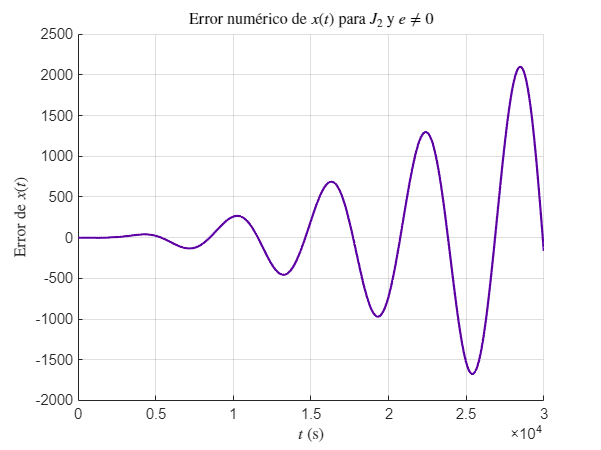

% Resolución
X0  = [ x0,  y0,  z0,  dx0,  dy0,  dz0];
X0I = [x0I, y0I, z0I, dx0I, dy0I, dz0I];

opts = odeset('RelTol', 1e-12, 'AbsTol', 1e-5);
[dXdt, dXdt_Kepler, dXdt_J2J3_I] = kechichianMotion(t, X0, X0I, mu, J2, 0, R, a, e, n, INC, Omega, omega, theta_0, opts);

FAM = AM + dXdt_Kepler;
rFAM = FAM(:, 1:3);
rX   = dXdt(:, 1:3);

% Comparación
plotNumericError(FAM(:,1), dXdt(:,1), t,       'Error num\''erico de $x(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)',       'Error de $x(t)$', '#5C00A3');

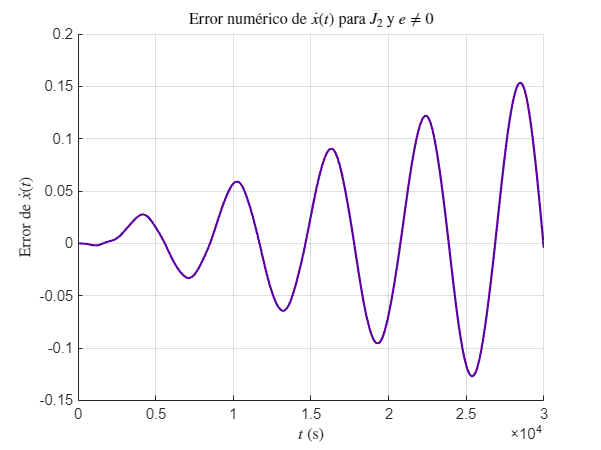

plotNumericError(FAM(:,4), dXdt(:,4), t, 'Error num\''erico de $\dot{x}(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $\dot{x}(t)$', '#5C00A3');

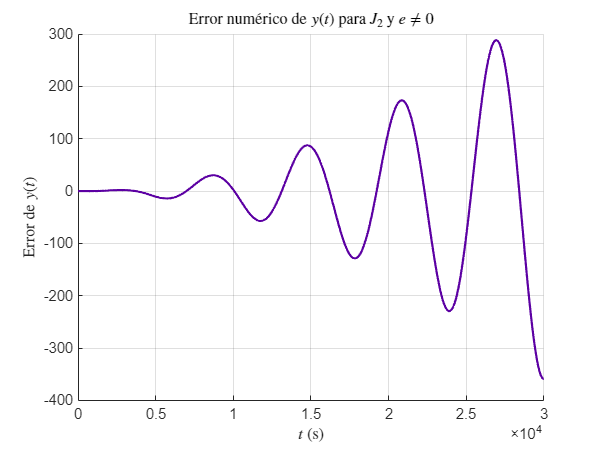

plotNumericError(FAM(:,2), dXdt(:,2), t,       'Error num\''erico de $y(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)',       'Error de $y(t)$', '#5C00A3');

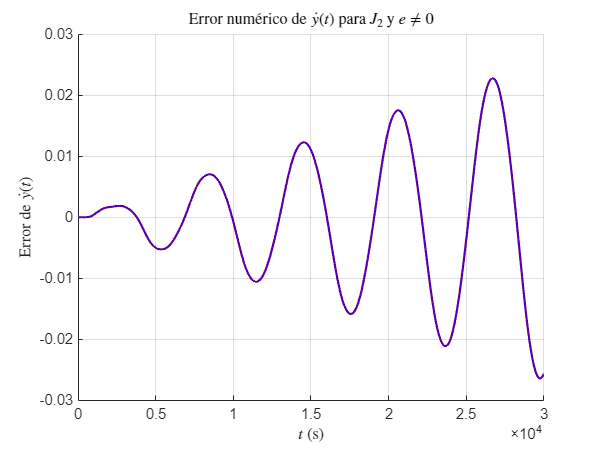

plotNumericError(FAM(:,5), dXdt(:,5), t, 'Error num\''erico de $\dot{y}(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $\dot{y}(t)$', '#5C00A3');

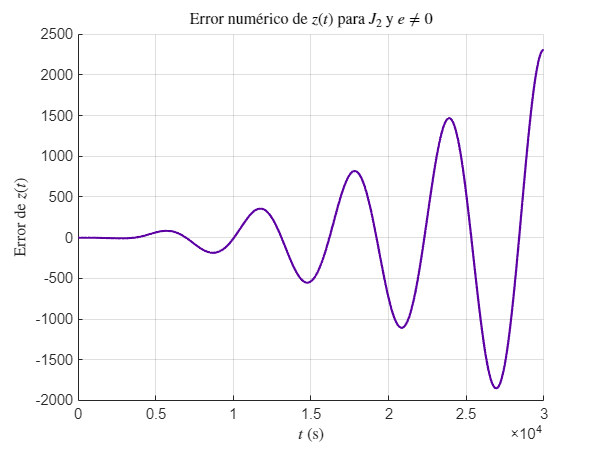

plotNumericError(FAM(:,3), dXdt(:,3), t,       'Error num\''erico de $z(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)',       'Error de $z(t)$', '#5C00A3');

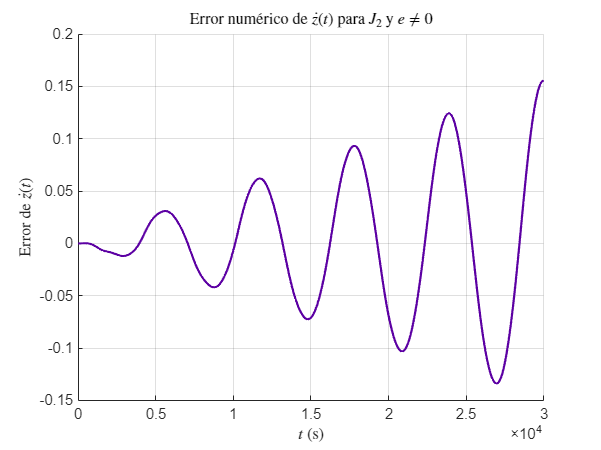

plotNumericError(FAM(:,6), dXdt(:,6), t, 'Error num\''erico de $\dot{z}(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $\dot{z}(t)$', '#5C00A3');

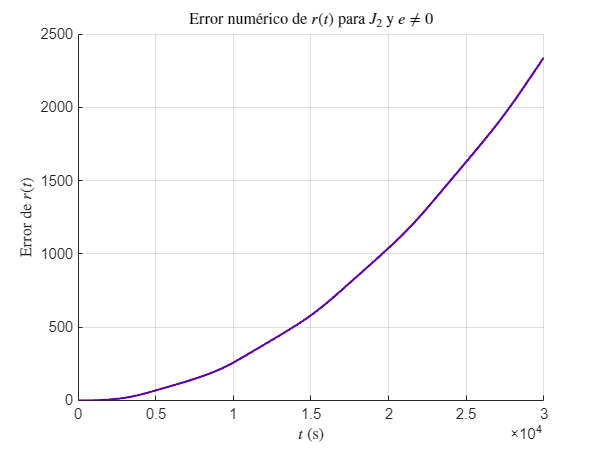


plotNumericErrorNorm(rFAM, rX, t, 'Error num\''erico de $r(t)$ para $J_2$ y $e \neq 0$', ...
    '$t$ (s)', 'Error de $r(t)$', '#5C00A3');